Importing Bitcoin alltime

bitcoin_alltime = readmatrix('../data/bitcoin_alltime.csv');
bitcoin_alltime = transpose(bitcoin_alltime(:,2));
for i=2:length(bitcoin_alltime)
    if isnan(bitcoin_alltime(i))
        bitcoin_alltime(i) = bitcoin_alltime(i-1);
    end
end
idx = 1:length(bitcoin_alltime);
disp("Bitcoin all time: (length: "+length(bitcoin_alltime)+")")
plot(idx,bitcoin_alltime)

Now we look at the clusters of the four data matrizes (sts_target,sts_opposed,whole_target,whole_opposed) calculated for different r,k,w values for the Bitcoin as target time series.

n = 1;
r = 8;

%ks = [3 5 7 11];
%ws = [8 16 32];

k = 5;
w = 8;

normMethods = ["none" "zscore" "norm" "scale" "range" "medianiqr"];
distMetrics = ["eukl" ""];
clusterAlgos = ["kmeans" "agglo" "gmm"];

currentClusterAlgo = clusterAlgos(1);
currentNorm = normMethods(2);
currentDistMetric = distMetrics(1);
reducedSamplingSize = true;
dimRed = true;
unify = true;

target_ts = bitcoin_alltime;
opposing_ts = createRandomWalk(target_ts);
%opposing_ts = bitcoin_alltime;



meaningfulness_sts = 0;
meaningfulness_whole = 0;

sts_target_matrix = toStsMatrix(target_ts, w);
sts_opposing_matrix = toStsMatrix(opposing_ts, w);

whole_target_matrix = toRandomSamplingMatrix(target_ts, w, reducedSamplingSize);
whole_opposing_matrix = toRandomSamplingMatrix(opposing_ts, w, reducedSamplingSize);

sts_target_matrix = scaleFeatureMatrix(sts_target_matrix, currentNorm);
sts_opposing_matrix = scaleFeatureMatrix(sts_opposing_matrix, currentNorm);

whole_target_matrix = scaleFeatureMatrix(whole_target_matrix, currentNorm);
whole_opposing_matrix = scaleFeatureMatrix(whole_opposing_matrix, currentNorm);


if dimRed && w>8
    [~,score,~] = pca(sts_target_matrix);
    sts_target_matrix = score;
    
    [~,score,~] = pca(whole_target_matrix);
    whole_target_matrix = score;
    
    [~,score,~] = pca(sts_opposing_matrix);
    sts_opposing_matrix = score;
    
    [~,score,~] = pca(whole_opposing_matrix);
    whole_opposing_matrix = score;
end
for z = 1:n
    sts_target_centers = zeros(k,w);
    whole_target_centers = zeros(k,w);
    sts_opposing_centers = zeros(k,w);
    whole_opposing_centers = zeros(k,w);

    for i = 1:r
        sts_target_centers(:,:,i) = clusterFunctions(sts_target_matrix,k,currentClusterAlgo,unify);
        sts_opposing_centers(:,:,i) = clusterFunctions(sts_opposing_matrix,k,currentClusterAlgo,unify);
        whole_target_centers(:,:,i) = clusterFunctions(whole_target_matrix,k,currentClusterAlgo,unify);
        whole_opposing_centers(:,:,i) = clusterFunctions(whole_opposing_matrix,k,currentClusterAlgo,unify);    
    end
    
    meaningfulness_sts = meaningfulness_sts + clusteringMeaningfulness(sts_target_centers, sts_opposing_centers, currentDistMetric);
    meaningfulness_whole =  meaningfulness_whole + clusteringMeaningfulness(whole_target_centers, whole_opposing_centers, currentDistMetric);
end

disp('--------------------------------------------------------------------------');    

--------------------------------------------------------------------------


disp('STS target centers:');

STS target centers:


disp('');
disp(sts_target_centers);


(:,:,1) =

   -1.2351   -0.9694   -0.5566   -0.0623    0.3896    0.6981    0.8585    0.8773
    1.3637    0.7594   -0.0435   -0.5947   -0.6550   -0.4534   -0.2421   -0.1343
   -0.9558   -0.3221    0.3324    0.7258    0.7487    0.3149   -0.2522   -0.5917
   -0.2958   -0.4537   -0.5859   -0.6410   -0.4341    0.1015    0.8021    1.5070
    0.6857    0.7488    0.7260    0.5020   -0.0332   -0.5696   -0.9398   -1.1199


(:,:,2) =

   -1.2454   -0.9693   -0.5543   -0.0506    0.4028    0.7090    0.8475    0.8602
    0.6954    0.7517    0.7191    0.4946   -0.0368   -0.5659   -0.9380   -1.1201
   -0.3299   -0.4742   -0.5837   -0.6294   -0.4194    0.1105    0.8198    1.5063
   -0.9396   -0.3087    0.3378    0.7300    0.7479    0.3031   -0.2645   -0.6061
    1.3572    0.7469   -0.0466   -0.6046   -0.6618   -0.4564   -0.2301   -0.1047


(:,:,3) =

    1.0497    1.0302    0.6333   -0.0337   -0.5556   -0.7348   -0.7140   -0.6750
   -0.8724   -0.7928   -0.6487   -0.4444   -0.0428    0.4717    0.9576 

disp('--------------------------------------------------------------------------');

--------------------------------------------------------------------------


disp('STS opposing centers:');

STS opposing centers:


disp('');
disp(sts_opposing_centers);


(:,:,1) =

   -0.6488   -0.2533    0.2894    0.7658    0.7621    0.2878   -0.4128   -0.7901
    1.0056    0.8424    0.5722    0.2346   -0.0984   -0.4806   -0.9052   -1.1706
    0.9167    0.6326    0.1650   -0.3930   -0.8281   -0.7435   -0.1086    0.3590
   -1.2873   -0.9370   -0.3277    0.0661    0.3366    0.5556    0.7438    0.8499
   -0.1095   -0.3725   -0.8435   -0.7655   -0.2357    0.3861    0.8469    1.0935


(:,:,2) =

    1.1325    0.9254    0.5542    0.0956   -0.2439   -0.5793   -0.8639   -1.0206
    0.7576    0.3828   -0.2210   -0.6657   -0.6895   -0.3193    0.1784    0.5767
   -1.2277   -0.8934   -0.3283    0.2729    0.7069    0.7809    0.4614    0.2272
   -0.8067   -0.7360   -0.5974   -0.3935   -0.0860    0.3761    0.9478    1.2957
   -0.3226    0.0493    0.5495    0.8837    0.5519   -0.0677   -0.6343   -1.0097


(:,:,3) =

   -0.1530   -0.1040    0.1274    0.6561    0.7491    0.3997   -0.4960   -1.1793
   -1.0468   -0.9047   -0.6503   -0.1822    0.3159    0.6933    0.8820 

disp('--------------------------------------------------------------------------');

--------------------------------------------------------------------------


disp('Whole target centers:');

Whole target centers:


disp('');
disp(whole_target_centers);


(:,:,1) =

   -0.5772   -0.6601   -0.6726   -0.4087   -0.2450    0.1157    0.8784    1.5696
    1.1362    1.0774   -0.1082   -0.5434   -0.6960   -0.4832   -0.2463   -0.1366
    0.5264    0.4861    0.7265    0.7702    0.0036   -0.7068   -0.8586   -0.9473
   -1.3343   -0.5277    0.5110    0.4691    0.8295    0.5023   -0.0400   -0.4098
   -1.0689   -1.0356   -0.7422   -0.0965    0.4953    0.7764    0.9035    0.7681


(:,:,2) =

    0.4394    0.2650    0.3785    0.7360    0.5967   -0.1399   -0.7848   -1.4909
   -0.8062   -0.8874   -0.7401   -0.3121    0.1512    0.4431    0.9400    1.2115
    1.1305    0.9094   -0.7560   -0.6636   -0.7597   -0.1697    0.1169    0.1921
    0.8080    0.9239    0.8199    0.1714   -0.5786   -1.0063   -0.7177   -0.4206
   -1.4552   -0.6666    0.2729    0.4924    0.6482    0.5668    0.1263    0.0153


(:,:,3) =

   -1.3493   -0.9229   -0.3624    0.1402    0.5990    0.6185    0.7196    0.5574
    1.2791    1.0698   -0.0522   -0.6105   -0.6998   -0.4848   -0.2782 

disp('--------------------------------------------------------------------------');

--------------------------------------------------------------------------


disp('Whole opposing centers:');

Whole opposing centers:


disp('');
disp(whole_opposing_centers);


(:,:,1) =

   -0.9942   -0.8055   -0.5106   -0.1852   -0.0356    0.4447    1.0965    0.9898
    0.7545    0.9090    0.5934    0.4084   -0.0821   -0.5133   -0.8391   -1.2308
    0.7563   -0.4417   -0.9281   -0.6047    0.0769    0.1273    0.0161    0.9980
   -1.1774   -0.5635    0.3099    0.5905    0.7280    0.5026   -0.0724   -0.3177
    1.1185    0.7509    0.3966   -0.3681   -0.9598   -0.8244   -0.2207    0.1070


(:,:,2) =

   -1.1582   -0.6547    0.1981    0.4802    0.8651    0.7163   -0.1022   -0.3445
    0.5107   -0.5129   -0.9638   -0.6847    0.0462    0.2360    0.2747    1.0938
    1.1405    0.7429    0.3572   -0.3601   -0.9389   -0.8060   -0.2464    0.1109
   -1.1187   -0.7713   -0.3440    0.0124   -0.0891    0.2998    1.0995    0.9114
    0.7282    0.9077    0.6055    0.4085   -0.0768   -0.5122   -0.8439   -1.2171


(:,:,3) =

   -0.8288   -0.2392    0.3670    0.7290    0.6746    0.4147   -0.2892   -0.8280
   -1.4632   -0.8249   -0.0902    0.2487    0.2337    0.3413    0.7661 

disp('--------------------------------------------------------------------------');

--------------------------------------------------------------------------


disp('');
disp('sts meaning: ');

sts meaning: 


disp((meaningfulness_sts/n));

    0.3749



disp('whole meaning: ');

whole meaning: 


disp((meaningfulness_whole/n));

    0.6284




%%%%%% visualize %%%%%%
n_comp = 2;

pca_sts_target_centers = zeros(k,n_comp,r);
pca_sts_opposing_centers = zeros(k,n_comp,r);
pca_whole_target_centers = zeros(k,n_comp,r);
pca_whole_opposing_centers = zeros(k,n_comp,r);

pca_sts_target_var = zeros(r,n_comp);
pca_sts_opposing_var = zeros(r,n_comp);
pca_whole_target_var = zeros(r,n_comp);
pca_whole_opposing_var = zeros(r,n_comp);
    
for i = 1:r
    [~,score,~,~,var,~] = pca(sts_target_centers(:,:,i), 'NumComponents', n_comp);
    pca_sts_target_centers(:,:,i) = score;
    pca_sts_target_var(i,:) = var(1:n_comp);
    
    [~,score,~,~,var,~] = pca(sts_opposing_centers(:,:,i), 'NumComponents', n_comp);
    pca_sts_opposing_centers(:,:,i) = score;
    pca_sts_opposing_var(i,:) = var(1:n_comp);
    
    [~,score,~,~,var,~] = pca(whole_target_centers(:,:,i), 'NumComponents', n_comp);
    pca_whole_target_centers(:,:,i) = score;
    pca_whole_target_var(i,:) = var(1:n_comp);
    
    [~,score,~,~,var,~] = pca(whole_opposing_centers(:,:,i), 'NumComponents', n_comp);
    pca_whole_opposing_centers(:,:,i) = score;
    pca_whole_opposing_var(i,:) = var(1:n_comp);
    
end

disp('--------------------------------------------------------------------------')    

--------------------------------------------------------------------------


disp('STS target centers:')

STS target centers:


disp('')
disp(pca_sts_target_centers)


(:,:,1) =

    2.0329   -0.3945
   -1.4103    1.3599
    0.0396   -1.6500
    1.4877    1.1702
   -2.1499   -0.4857


(:,:,2) =

    2.0238   -0.4106
   -2.1553   -0.4750
    1.5129    1.1502
    0.0095   -1.6432
   -1.3909    1.3786


(:,:,3) =

    2.0806    0.4113
   -2.1013    0.5228
    1.3480   -1.3771
    0.2174    1.5795
   -1.5448   -1.1365


(:,:,4) =

   -2.1392   -0.5058
    1.4538    1.1832
   -1.4326    1.3454
    2.0447   -0.3685
    0.0733   -1.6543


(:,:,5) =

    1.4533    1.1776
    2.0423   -0.3697
    0.0717   -1.6533
   -2.1455   -0.5033
   -1.4218    1.3487


(:,:,6) =

    1.4528    1.1831
   -1.4337    1.3439
   -2.1396   -0.5074
    0.0738   -1.6502
    2.0467   -0.3693


(:,:,7) =

    1.6041    1.0461
   -1.2367    1.4516
   -2.2225   -0.3852
    1.9618   -0.4662
   -0.1067   -1.6463


(:,:,8) =

    2.0467   -0.3693
   -2.1396   -0.5074
    1.4528    1.1831
   -1.4337    1.3439
    0.0738   -1.6502



disp('____')

____


disp(pca_sts_target_var)

   66.5710   32.5316
   66.6545   32.4798
   66.9990   31.5798
   66.4152   32.5614
   66.4016   32.5466
   66.4901   32.4917
   66.5172   32.3626
   66.4901   32.4917



disp('--------------------------------------------------------------------------')

--------------------------------------------------------------------------


disp('STS opposing centers:')

STS opposing centers:


disp('')
disp(pca_sts_opposing_centers)


(:,:,1) =

   -0.2251    1.6509
   -2.1926    0.1971
   -0.9479   -1.3390
    1.9346    0.5223
    1.4311   -1.0313


(:,:,2) =

    2.2445   -0.2235
    0.3021   -1.5422
   -1.5324    0.9920
   -1.9338   -0.6225
    0.9196    1.3963


(:,:,3) =

   -0.8861   -1.2680
    1.9547   -0.2152
    0.5028    1.6678
    0.5682   -0.7152
   -2.1397    0.5305


(:,:,4) =

   -0.5955    1.4436
    1.7987    0.8329
    1.7099   -0.8402
   -0.6562   -1.5264
   -2.2570    0.0901


(:,:,5) =

    2.2395   -0.1981
    0.1537   -1.3618
   -1.1722   -0.7337
   -1.8386    0.6609
    0.6175    1.6327


(:,:,6) =

    2.1340    0.2554
   -2.0713    0.1312
   -0.6574   -1.2232
   -0.1986    1.7553
    0.7933   -0.9187


(:,:,7) =

    2.2395    0.2111
    0.4726   -1.5184
   -0.1364    1.6885
   -0.6433   -0.2027
   -1.9323   -0.1784


(:,:,8) =

    2.2382    0.3145
   -1.9268   -0.2039
   -0.2714    1.6978
   -0.7176   -0.4224
    0.6776   -1.3859



disp('____')

____


disp(pca_sts_opposing_var)

   64.8045   33.0731
   67.3229   32.0892
   57.3600   30.7293
   67.3356   32.5622
   59.0813   32.1380
   58.5362   32.3945
   55.7742   31.2767
   57.7763   30.2917



disp('--------------------------------------------------------------------------')

--------------------------------------------------------------------------


disp('Whole target centers:')

Whole target centers:


disp('')
disp(pca_whole_target_centers)


(:,:,1) =

   -1.4705    1.1168
    1.7544    1.2835
    2.0633   -0.7220
   -0.4787   -1.6231
   -1.8684   -0.0552


(:,:,2) =

    1.1477   -1.3643
   -2.1670    0.7880
    0.8057    1.6948
    1.7635    0.0525
   -1.5500   -1.1711


(:,:,3) =

   -2.0483    0.7402
    1.3127   -1.3678
    1.8035    0.0425
   -1.9521   -0.9582
    0.8842    1.5432


(:,:,4) =

    1.6760    0.1463
   -1.6478   -1.1494
    1.2735   -1.3754
   -2.1730    0.8080
    0.8713    1.5705


(:,:,5) =

   -1.9641   -0.2409
   -1.5456    1.2161
    1.7526    1.3030
    2.0105   -0.6425
   -0.2535   -1.6356


(:,:,6) =

    1.0523   -0.6254
    1.3349    1.1787
   -1.9977    1.0739
   -1.9608   -1.0722
    1.5714   -0.5551


(:,:,7) =

   -1.2818    1.2565
    2.0009   -0.8111
    1.8518    1.1803
   -1.9310   -0.0058
   -0.6399   -1.6198


(:,:,8) =

   -2.1415    0.8564
   -1.5426   -1.1723
    1.7530   -0.0185
    0.8787    1.6916
    1.0525   -1.3572



disp('____')

____


disp(pca_whole_target_var)

   66.1484   30.2945
   60.0115   33.1676
   67.0703   27.8752
   62.1703   31.2822
   66.6620   31.3973
   68.8264   22.9068
   66.1925   31.3265
   58.9662   33.7007



disp('--------------------------------------------------------------------------')

--------------------------------------------------------------------------


disp('Whole opposing centers:')

Whole opposing centers:


disp('')
disp(pca_whole_opposing_centers)


(:,:,1) =

   -1.9776    0.2473
    1.9574   -0.8426
   -0.5530    1.3070
   -0.9442   -1.6010
    1.5174    0.8893


(:,:,2) =

   -1.0545   -1.5616
   -0.7621    1.3129
    1.6230    0.9306
   -1.8022    0.2095
    1.9958   -0.8913


(:,:,3) =

   -0.0723   -1.6304
   -1.8328   -0.4292
    1.1483    1.3826
   -1.4430    1.0930
    2.1997   -0.4160


(:,:,4) =

    1.9784   -0.8412
    0.8882    0.7355
   -1.9950    0.3922
    0.1421    1.3005
   -1.0137   -1.5870


(:,:,5) =

    0.4106   -1.2664
   -1.4386   -0.9520
    0.6705    1.6323
   -1.8279    0.8036
    2.1854   -0.2175


(:,:,6) =

   -2.0793    0.0976
    1.9621   -0.8329
    1.6130    0.9833
   -0.7703   -1.5827
   -0.7254    1.3347


(:,:,7) =

   -1.6990    0.8188
    0.7175    1.5764
   -0.9312   -1.2429
    2.2340   -0.4961
   -0.3213   -0.6561


(:,:,8) =

   -1.7448    0.6882
    2.2759   -0.1739
   -1.3132   -1.0703
    0.3815    1.6634
    0.4006   -1.1074



disp('____')

____


disp(pca_whole_opposing_var)

   61.1260   31.7184
   61.6620   31.2990
   62.8342   33.1480
   57.4241   33.1213
   60.3220   32.7584
   64.5526   32.3259
   53.9887   31.0043
   58.1678   32.0051



disp('--------------------------------------------------------------------------')

--------------------------------------------------------------------------


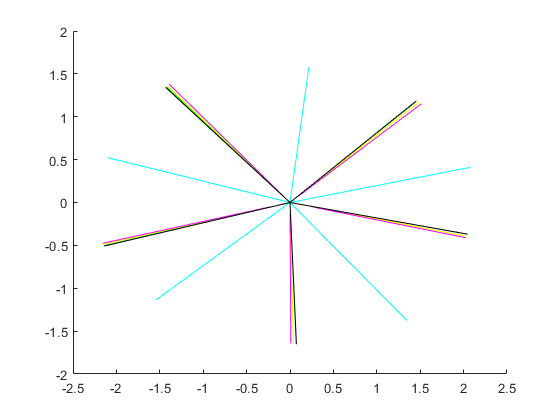

disp('')

colors = ['y','m','c','r','g','b','w','k'];

figure;
for i=1:size(pca_sts_target_centers,3)
    hold on;
    plotv(pca_sts_target_centers(:,:,i).', colors(i));
    hold off;
end

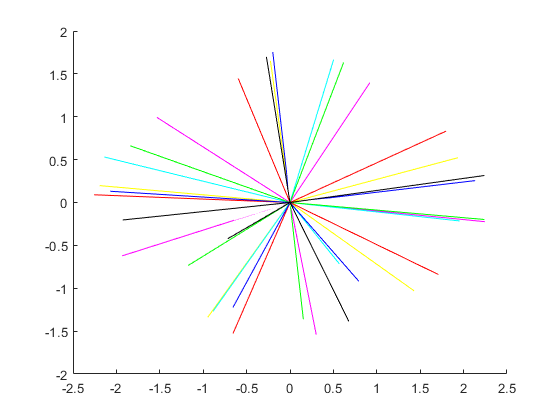


figure;
for i=1:size(pca_sts_opposing_centers,3)
    hold on;
    plotv(pca_sts_opposing_centers(:,:,i).', colors(i));
    hold off;
end

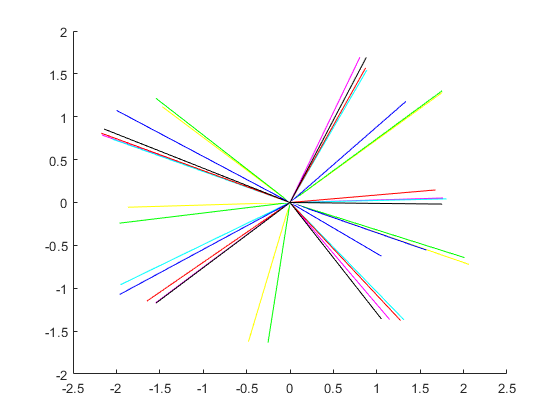


figure;
for i=1:size(pca_whole_target_centers,3)
    hold on;
    plotv(pca_whole_target_centers(:,:,i).', colors(i));
    hold off;
end

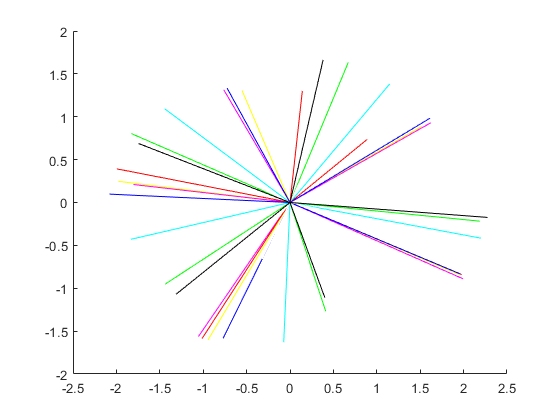


figure;
for i=1:size(pca_whole_opposing_centers,3)
    hold on;
    plotv(pca_whole_opposing_centers(:,:,i).', colors(i));
    hold off;
end